T = 0.03;
%delovna točka
U00 = 5.1
Y00 = 5.3464
t = 0:T:60;
simin_val = 5.1:0.25:6.1;
simin = simin_val'
% mrtva cona se konča pri 4.6
% gremo do cca 7
% najprej probat na 0.25V natančno

% vhodni signal
toWorkspace = 5;

Y_all = [Y_46.Data,Y_485.Data,Y_51.Data,Y_535.Data,Y_56.Data,Y_585.Data,Y_61.Data,Y_635.Data,Y_66.Data,Y_685.Data];

Y_end = mean(Y_all(end-30:end,:),1)

plot(simin_val,Y_end)



plot(Y_all(3))



%plot(Y_56.Data)
U_PRBS = prbs(10) + 5.1
U_PRBS_T = prbs(10) + 5.1
U = ones(7500,1)*5.1
U_T = ones(length(t)-length(U_PRBS_T),1)*5.1

plot(U)

figure
%plot(U_PRBS)
plot(Y_all)


U_prbs = [U;U_PRBS]
U_prbs_T = [U_T;U_PRBS_T]
U_prbs_11 = [U;prbs(11)+5.1]
U_prbs_12 = [U;prbs(12)+5.1]
%plot(U_prbs)

PRBS_true = [t',U_prbs_T]


% plot(out.simout)
% exp_1 = [PRBS_true,out.simout.Data]

t = final(70:end,1);
u = final(70:end,2)-5.6;
y = final(70:end,3)-4.9;


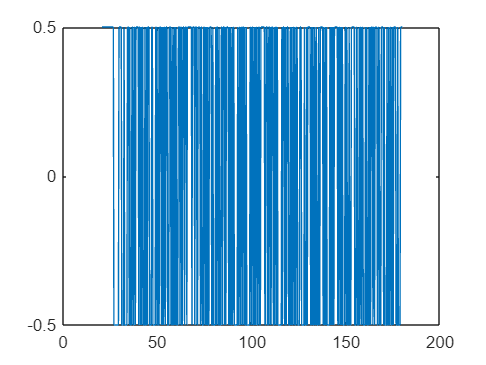

figure
plot(t,-u)

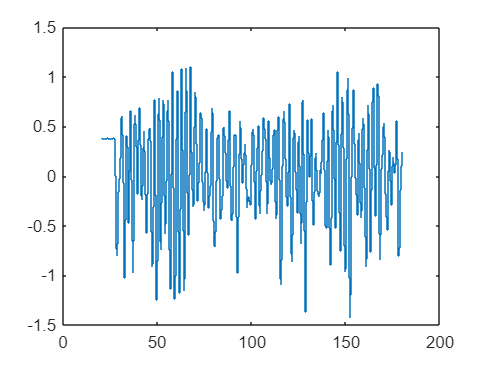

figure
stairs(t,y)

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F) %frequency vector

v =          0    0.0063    0.0125    0.0188    0.0251    0.0313    0.0376    0.0439    0.0501    0.0564    0.0627    0.0689    0.0752    0.0815    0.0877    0.0940    0.1003    0.1065    0.1128    0.1190    0.1253    0.1316    0.1378    0.1441    0.1504    0.1566    0.1629    0.1692    0.1754    0.1817    0.1880    0.1942    0.2005    0.2068    0.2130    0.2193    0.2256    0.2318    0.2381    0.2444    0.2506    0.2569    0.2632    0.2694    0.2757    0.2820    0.2882    0.2945    0.3008    0.3070


## FFT

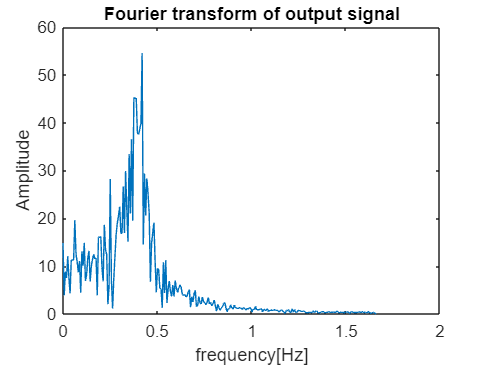

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

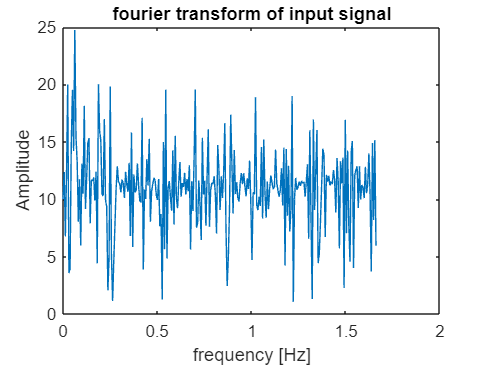


plot(v,abs(FT_input(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

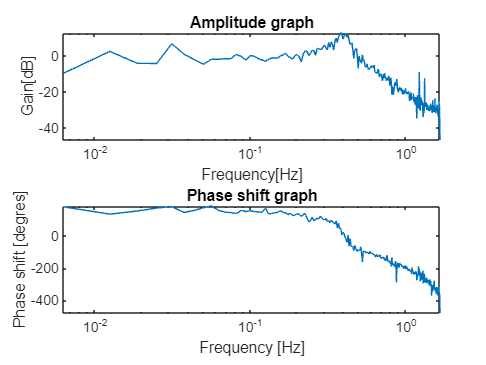

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

n = 2;
d = 2;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

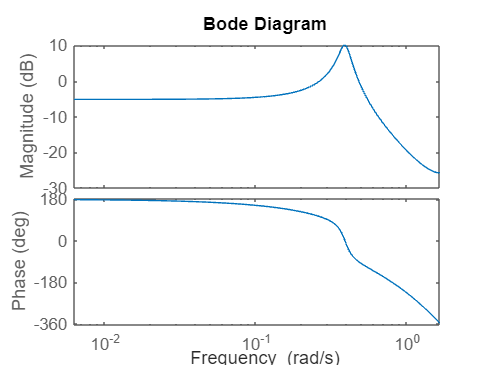


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
G = tf([Th(3) Th(4)],[1 Th(1) Th(2)], T); 
G.inputdelay = d;
%G = tf([Th(4) Th(5) Th(6)],[1 Th(1) Th(2) Th(3)], T);


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector

figure
bode(G,v);

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

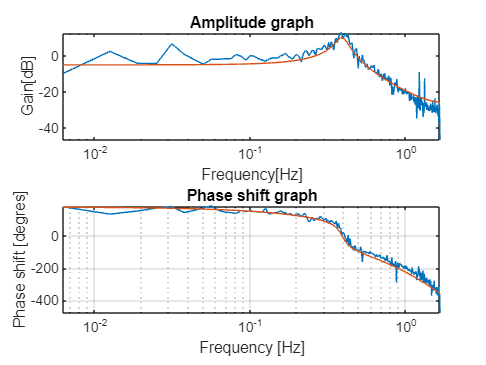

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

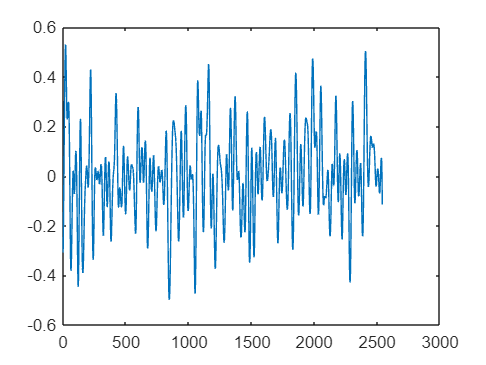

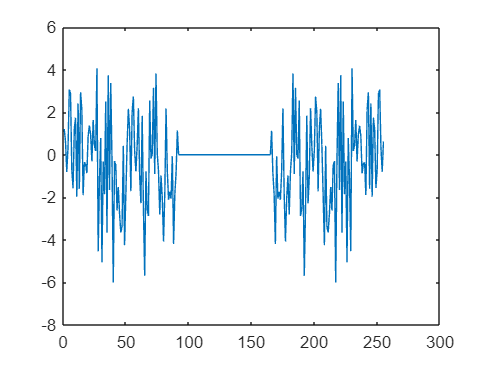

T = 0.0354

PRBS_true =          0    5.2922
    0.0354    5.3315
    0.0709    5.3758
    0.1063    5.4245
    0.1417    5.4767
    0.1772    5.5316
    0.2126    5.5884
    0.2480    5.6462
    0.2835    5.7043
    0.3189    5.7618


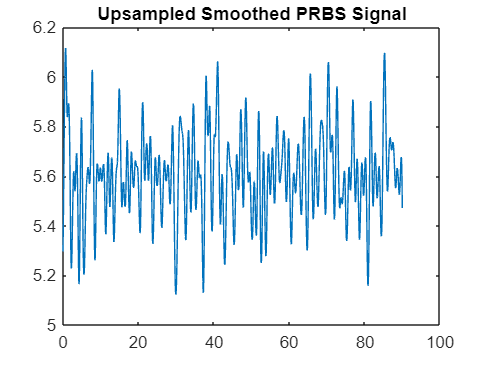

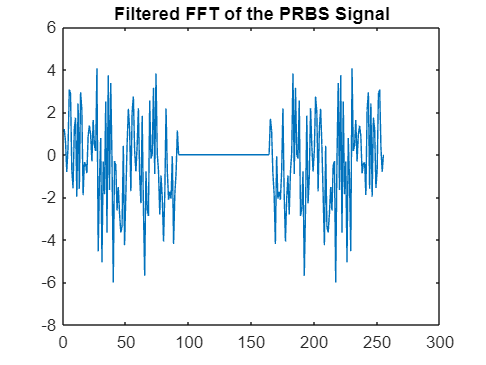

% prbs_9 = [prbs(8),prbs(8),prbs(8),prbs(8)];
% prbs_9t = prbs_9';
% prbs_10 = prbs_9t(:);
prbs_10 = prbs(8);
N_prbs = length(prbs_10);
random_array = rand(N_prbs, 1) - 0.5;
nice_array = random_array .* prbs_10;

## tier 2

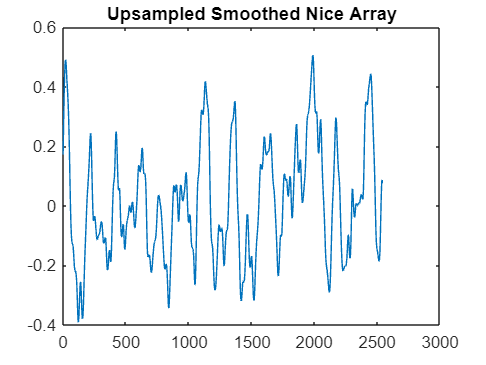

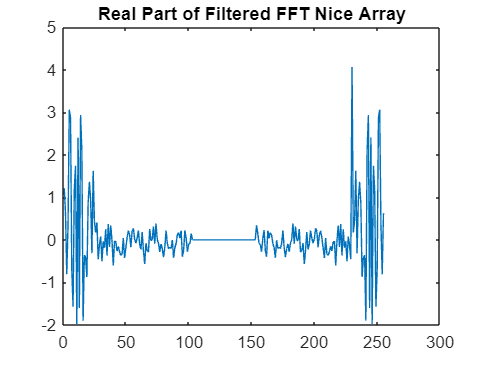

% Assume prbs_10 and nice_array are defined as shown in your message

% Calculate the FFT of the nice_array
fft_nice_array = fft(nice_array);

% Determine the total number of points
N_prbs = length(prbs_10);

% Calculate the index for 20% of the frequencies
cutoff_20_idx = ceil(0.2 * (N_prbs / 2));

% Calculate the index for 80% of the frequencies
cutoff_80_idx = ceil(0.8 * (N_prbs / 2));

% Create a filter mask
filter_mask = zeros(N_prbs, 1); % Start with all zeros to cut off high frequencies

% Pass the lowest 20% of frequencies
filter_mask(1:cutoff_20_idx+1) = 1; % Include the zero-frequency bin
filter_mask(end-cutoff_20_idx+1:end) = 1; % Symmetric for the negative frequencies

% Attenuate the next portion up to 80% of frequencies by 80%
filter_mask(cutoff_20_idx+1:cutoff_80_idx) = 0.1; % Lower the amplitude by 80%
filter_mask(end-cutoff_80_idx+1:end-cutoff_20_idx) = 0.1; % Apply symmetrically

% Apply the filter mask to the FFT of the nice_array
filtered_fft_nice_array = fft_nice_array .* filter_mask;

% Perform the inverse FFT to get the filtered array
smoothed_nice_array = ifft(filtered_fft_nice_array);

% Normalize the data to be between -0.5 and 0.5
max_val = max(abs(smoothed_nice_array));
smoothed_nice_array = (smoothed_nice_array / max_val) * 0.5;

% In case the imaginary part is non-zero due to numerical errors, take only the real part
smoothed_nice_array = real(smoothed_nice_array);

% Upsample the smoothed array by a factor of 10
upsampled_rate = 10;
upsampled_smoothed_nice_array = interp1(1:N_prbs, smoothed_nice_array, 1:1/upsampled_rate:N_prbs, 'spline');

% Plotting the results
figure
plot(upsampled_smoothed_nice_array)
title('Upsampled Smoothed Nice Array')

figure
plot(real(filtered_fft_nice_array))
title('Real Part of Filtered FFT Nice Array')

% Calculate the time vector for plotting
u_new = upsampled_smoothed_nice_array(1:end-40)
L = length(u_new);
Ts = 90; % Total time span
T = Ts / (L-1); % Time step
t = 0:T:Ts+10.8;

% Create a table with time and data
temp = u_new'+5.6
oness = ones(1,300)*5.6
U_true = [oness';temp];
U_signal = [t', U_true];

## T3

% Define the signal parameters
Fs = 100; % Increase the sampling frequency for better resolution
Ts = 1/Fs;
T = 120;                 % Total time in seconds
t = linspace(0, T, T*Fs);  % Time vector from 0 to T seconds with Fs samples

% Frequency range
f0 = 0.05;              % Start frequency in Hz
f1 = 5;                 % End frequency in Hz

% Generate the cosine chirp signal
% Adding 'phase', pi/2 to generate a cosine instead of a sine wave chirp
signal = chirp(t, f0, T, f1, 'linear', 90); % phase in degrees

% Plot the signal
figure;
plot(t, signal);
title('Cosine Chirp Signal from 0.05 Hz to 5 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Optionally, you can listen to the signal if you want to check its acoustic characteristics
% sound(signal, Fs); % Uncomment this line if you want to listen to the signal


temp = signal'+5.6
oness = ones(1,2000)*5.6
U_true = [oness';temp];
t = linspace(0, (T+20), (T+20)*Fs)
U_signal = [t', U_true];


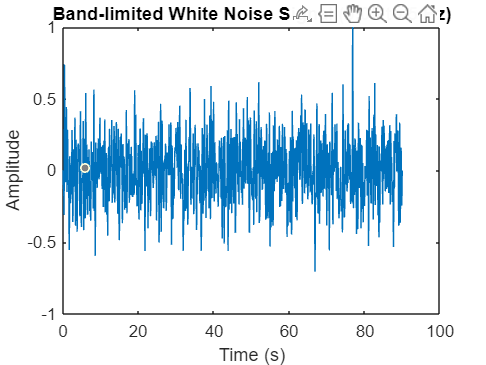

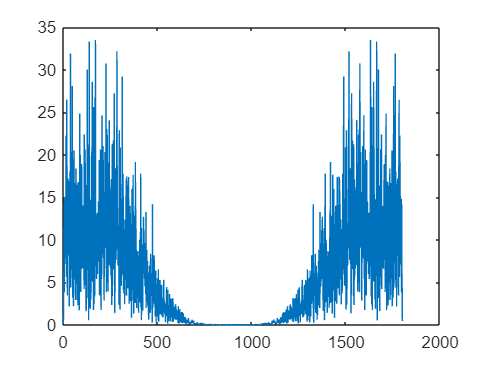

figure
plot(U_signal(:,1),U_signal(:,2))

## Analaysis

t = finish(1:end-299,1);
u = finish(300:end,2)-5.6;
y = finish(300:end,3)-4.93;

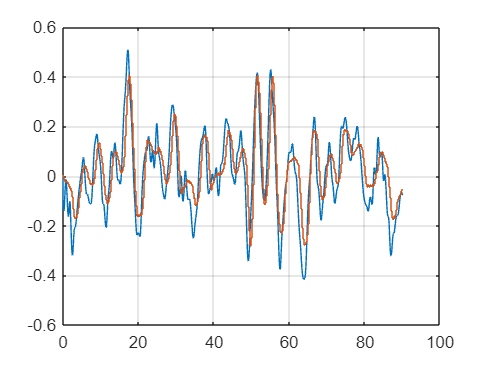

figure
plot(t,-u)
hold on
grid on
stairs(t,y)


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F) %frequency vector

v =          0    0.0111    0.0222    0.0333    0.0444    0.0555    0.0666    0.0777    0.0888    0.0999    0.1110    0.1221    0.1332    0.1443    0.1554    0.1665    0.1776    0.1887    0.1998    0.2109    0.2220    0.2331    0.2442    0.2554    0.2665    0.2776    0.2887    0.2998    0.3109    0.3220    0.3331    0.3442    0.3553    0.3664    0.3775    0.3886    0.3997    0.4108    0.4219    0.4330    0.4441    0.4552    0.4663    0.4774    0.4885    0.4996    0.5107    0.5218    0.5329    0.5440


## FFT

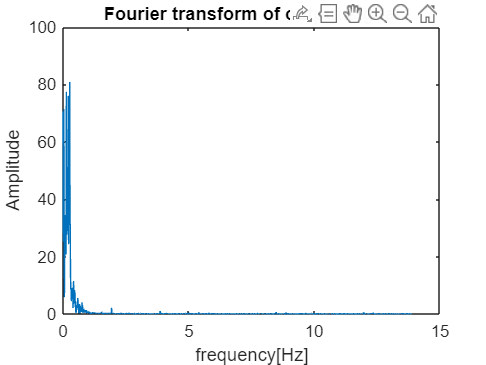


FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

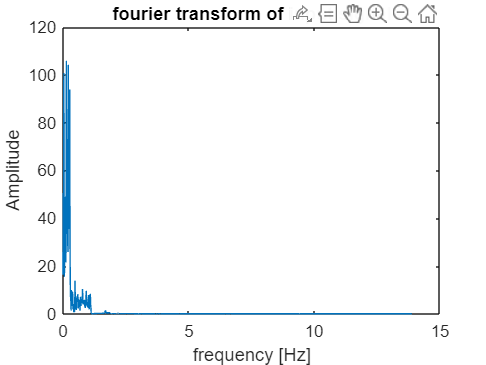


plot(v,abs(FT_input(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

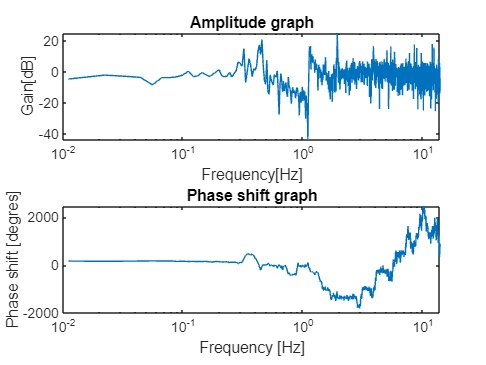


G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

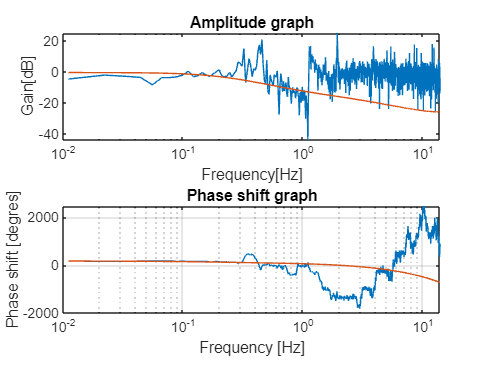



n = 2;
d = 4;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
G = tf([Th(3) Th(4)],[1 Th(1) Th(2)], T); 
G.inputdelay = d;
%G = tf([Th(4) Th(5) Th(6)],[1 Th(1) Th(2) Th(3)], T);

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector

figure
% bode(G,v);
[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:end/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:end/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")